## Histogram Count Probabilities

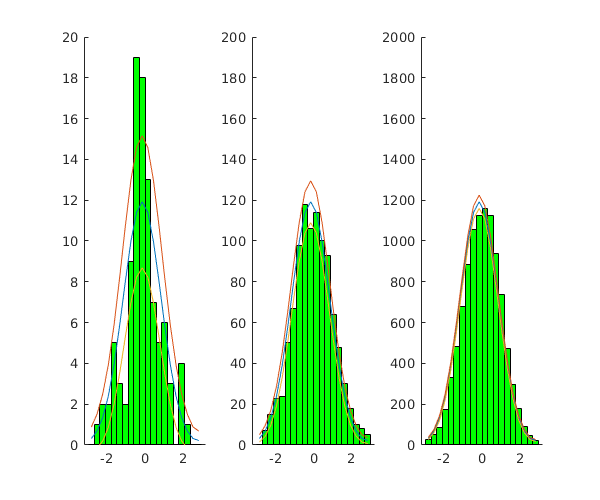

figure;
hold on;

t = linspace(-3, 4, 100);
N = [100, 1000, 10000];
edges = -3:0.3:3;
    centers = (edges(1:end-1) + edges(2:end))/2;

for i = 1:length(N)
    
    cdf = normcdf(centers);
    bin_probabilities = [cdf(2:end), 1] - cdf;
    mean = N(i) * bin_probabilities;
    std_dev = sqrt(mean .* (1 - bin_probabilities));
    
    subplot(1,length(N),i);
    
    samples = randn(N(i), 1);
    [counts] = histcounts(samples, edges);
    hold on;
    ylim([0, N(i)/5]);
    bar(centers, counts, 1, 'g');
    plot(centers, mean);
    plot(centers, mean + std_dev);
    plot(centers, mean - std_dev);
end

function stairs2(x,y)
    A = zeros(2, length(x));
    B = zeros(2, length(x));
    for i=1:length(x)-1
        A(:,i) = [x(i) x(i+1)];
        B(:,i) = [y(i) y(i)];
    end
    plot(A,B,'Color','black');
end